DTLZ1 Test function of Deb et a. 2001

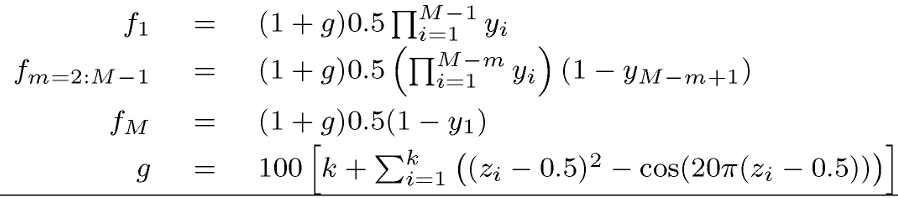

[https://tik-old.ee.ethz.ch/file//3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf](https://tik-old.ee.ethz.ch/file//3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf)

function Fx = AMALGAM_DTLZ1(x,M)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%AMALGAM_DTLZ1: DTZL1 m-variate test function of Deb et al. 2001          %
%                                                                         %
%  SYNOPSIS                                                               %
%   Fx = AMALGAM_DTZL1(x,m)                                               %
%  where                                                                  %
%   x       [input] 1xd parameter vector                                  %
%   m       [input] # objective functions                                 %
%   Fx      [outpt] m objective function values                           %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
% DTZL1 example from the following paper                                  %
%  Deb, K., L. Thiele, M. Laumanns, and E. Zitzler (2001), Scalable Test  %
%      Problems for Evolutionary Multi-Objective Optimization. Kanpur,    %
%      India: Kanpur Genetic Algorithms Lab. (KanGAL), Indian Institute   %
%      of Technology, KanGAL Report 2001001                               % 
%      https://tik-old.ee.ethz.ch/file// ...                              %
%          3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf                 %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
%  © Written by Jasper A. Vrugt, Jan. 2005                                %
%  Los Alamos National Laboratory                                         %
%  University of California Irvine                                        %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %

Fx = nan(M,1);                                      % # objectives
d = numel(x);                                       % # parameters
k = d - M + 1;                                      % integer k 
g = 100*(k + sum((x(M:d)-.5).^2 - cos(20*pi*(x(M:d) -.5))));
Fx(1) = .5 * prod(x(1:M-1)) * (1+g);
for m = 2:M-1
    Fx(m) = .5 * prod(x(1:M-m)) * (1-x(M-m+1)) * (1 + g);
end
Fx(M) = .5 * (1-x(1)) * (1 + g);

% xnotM = x(1:M-1);                                   % Remaining parameters 
% xM = x(M:d);                                        % Last k variables: xM  
% % k1 = d - k;
% % g = 100 * (k + sum( (xM - .5).^2 ...                % g(xM)
% %     - cos(20*pi*(xM - .5))));                
% % Fx(1) = .5 * (1 + g) * prod(xnotM(1:k1));           % f_1(x)
% % Fx(1) = .5 * prod(xnotM) * (1+g);
% % for m = 2:M - 1
% %     Fx(m) = .5 * (1 + g) * ...                      % f_m(x)
% %         prod(xnotM(1:k1-m+1))*(1 - xnotM(k1-m+2));
% % end
% % Fx(M) = .5 * (1 + g) * (1 - xnotM(1));              % f_M(x)

end